% Thomas Monfre
% Dartmouth College CS 11, Spring 2018
% Short Assignment 5: Mixed Images

% Problem 1b: regenerate source images S1 and S2 
% without using for-loops

% clear workspace, load images/cs11lib functions
clear;
load('s5Images.mat');
addpath('cs11lib/');

% display M1 and M2 for reference
fprintf('%s\n', 'Original image M1');

Original image M1


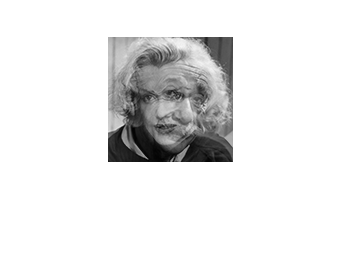

display_image(M1);


fprintf('%s\n', 'Original image M2');

Original image M2


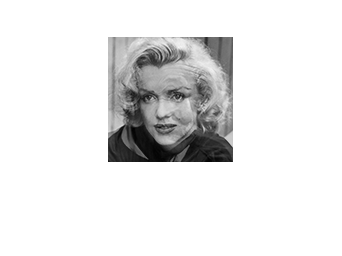

display_image(M2); 


% images M1 and M2 can be modeled by following equations:
% M1 = 0.45*S1 + 0.55*S2
% M2 = 0.65*S1 + 0.35*S2

% create a matrix of coefficients from equations above
M = [0.45 0.55 ; 0.65 0.35];

% convert each matrix image to 15625x1 column vector, then transpose to a 1x15625 row vector
M1v = M1(:)';
M2v = M2(:)';

% set v to be a column vector of each matrix-vector -- in effect, a 2x15625 matrix
v = [M1v ; M2v];

% calculate the resultant 2x15625 vector u
u = inv(M) * v;

% separate the row vectors of each image into S1v and S2v
S1v = u(1,:);
S2v = u(2,:);

% reshape into the original 125x125 matrix size
S1 = reshape(S1v, [125,125]);
S2 = reshape(S2v, [125,125]);

% display S1 and S2
fprintf('%s\n', 'Problem 1b');

Problem 1b


fprintf('%s\n', 'Solution image M1');

Solution image M1


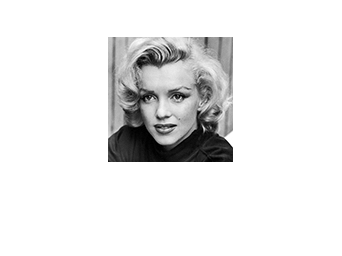

display_image(S1);


fprintf('%s\n', 'Solution image M2');

Solution image M2


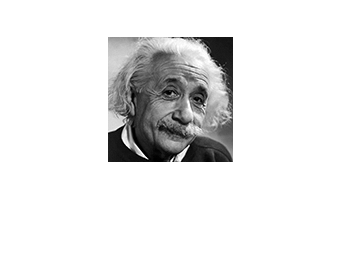

display_image(S2); 